MN2

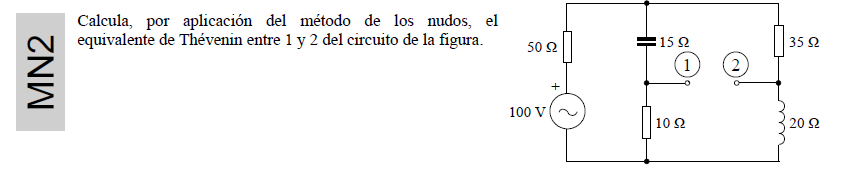

Option 1

clear all 
close all
clc

Matrix (A) and independent vector (B) definition Ax=B


A=[1/50,-1/50,0,0,1;
  -1/50,1/50+1/(-15*1i)+1/35,-1/(-1i*15),-1/35,0;
  0, -1/(-1i*15), 1/(-1i*15)+1/10,0,0;
  0, -1/35, 0, 1/35+1/(20*1i),0;
  1,0,0,0,0]

A =    0.0200 + 0.0000i  -0.0200 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i
  -0.0200 + 0.0000i   0.0486 + 0.0667i   0.0000 - 0.0667i  -0.0286 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 - 0.0667i   0.1000 + 0.0667i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.0286 + 0.0000i   0.0000 + 0.0000i   0.0286 - 0.0500i   0.0000 + 0.0000i
   1.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i



B=[0;0;0;0;100]

B =      0
     0
     0
     0
   100



sol=inv(A)*B

sol = 	1.0e+02 *

   1.0000 + 0.0000i
   0.2269 - 0.1062i
   0.1188 + 0.0720i
   0.1016 + 0.0716i
  -0.0155 - 0.0021i


abs(sol)

ans =   100.0000
   25.0510
   13.8958
   12.4288
    1.5608


angle(sol)*180/pi

ans =          0
  -25.0836
   31.2263
   35.1715
 -172.1784


Computing the Thévenin

v3=sol(3)

v3 = 11.8827 + 7.2039i

v4=sol(4)

v4 = 10.1597 + 7.1593i

uth=v3-v4

uth = 1.7230 + 0.0446i

uthm=abs(uth)

uthm = 1.7236

utha=angle(uth)*180/pi

utha = 1.4815


angle(uth)

ans = 0.0259

z=inv(A)

z =    0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i
   0.0000 + 0.0000i  11.3442 - 5.3101i   5.9413 + 3.6019i   5.0798 + 3.5797i   0.2269 - 0.1062i
   0.0000 + 0.0000i   5.9413 + 3.6019i   7.0887 - 0.7649i  -0.0891 + 3.4460i   0.1188 + 0.0720i
   0.0000 + 0.0000i   5.0798 + 3.5797i  -0.0891 + 3.4460i   8.3238 +18.1463i   0.1016 + 0.0716i
   1.0000 + 0.0000i   0.2269 - 0.1062i   0.1188 + 0.0720i   0.1016 + 0.0716i  -0.0155 - 0.0021i


zth=z(3,3)+z(4,4)-z(3,4)-z(4,3)

zth = 15.5908 + 10.4894i

Option 2. Using Norton equivalent

Matrix (A) and independent vector (B) definition Ax=B

A=[1/50+1/(-1i*15)+1/35, -1/(-1i*15), -1/35;
    -1/(-1i*15),1/(-1i*15)+1/10,0;
    -1/35, 0, 1/35+1/(1i*20)]

A =    0.0486 + 0.0667i   0.0000 - 0.0667i  -0.0286 + 0.0000i
   0.0000 - 0.0667i   0.1000 + 0.0667i   0.0000 + 0.0000i
  -0.0286 + 0.0000i   0.0000 + 0.0000i   0.0286 - 0.0500i



B=[100/50;0;0]

B =      2
     0
     0



sol=inv(A)*B

sol =   22.6885 -10.6201i
  11.8827 + 7.2039i
  10.1597 + 7.1593i


abs(sol)

ans =    25.0510
   13.8958
   12.4288


angle(sol)*180/pi

ans =   -25.0836
   31.2263
   35.1715


Computing the Thévenin

% Now, positions are different!
v3=sol(2)

v3 = 11.8827 + 7.2039i

v4=sol(3)

v4 = 10.1597 + 7.1593i


uth=v3-v4

uth = 1.7230 + 0.0446i

uthm=abs(uth)

uthm = 1.7236

utha=angle(uth)*180/pi

utha = 1.4815


z=inv(A)

z =   11.3442 - 5.3101i   5.9413 + 3.6019i   5.0798 + 3.5797i
   5.9413 + 3.6019i   7.0887 - 0.7649i  -0.0891 + 3.4460i
   5.0798 + 3.5797i  -0.0891 + 3.4460i   8.3238 +18.1463i


zth=z(2,2)+z(3,3)-z(2,3)-z(3,2)

zth = 15.5908 + 10.4894i